## **PL03 Variáveis e Distribuições Aleatórias**

#### **Ex1. **Variável aleatória X correspondente à face que sai no lançamento de um dado.

a) Gráfico da função massa de probabilidade de x:

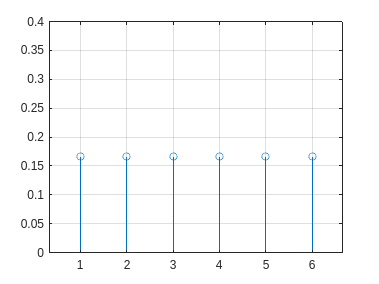

x = 1:6;
prob_x = ones(1,6) * 1/6;

stem(x,prob_x);
ylim([0 0.4]);
grid on;

b) Gráfico em subplot com o anterior da função de distribuição cumulativa de x:

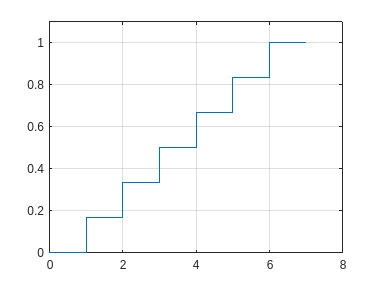

x = 1:6;
prob_x = ones(1,6) * 1/6;
xx = [0 x 7];
prob_xx = [0 prob_x 0];

stairs(xx, cumsum(prob_xx));
ylim([0 1.1]);
xlim([0 8]);
grid on;

#### **Ex2. **Caixa contém noventa notas de 5, nove notas de 50 e uma nota de 100.

a) Espaço de amostragem da experiência aleatória "retirar uma nota da caixa" e probabilidades dos acontecimentos elementares.

**R:** S = {nota1, nota2, ..., nota99, nota100}                     % espaço de amostragem

b) Variável aleatória X (valor de uma qualquer nota retirada da caixa. Seu espaço de amostragem e função massa de probabilidade de X.

**R: **Sx = {5, 50, 100}

% x1 = 5;
% x2 = 50;
% x3 = 100;
prob_x1 = 90/100

prob_x1 = 0.9000

prob_x2 = 9/100

prob_x2 = 0.0900

prob_x3 = 1/100

prob_x3 = 0.0100

c) Função de distribuição acumulada de X, Fx(x):

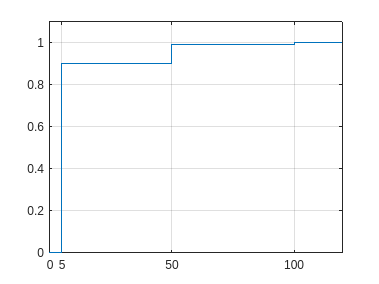

x = [5 50 100];
prob_x = [0.9 0.09 0.01];
xx = [0 x 120];
prob_xx = [0 prob_x 0];

%% cumsum = cumulative sum
stairs(xx, cumsum(prob_xx))
ylim([0 1.1]);
xlim([0 120]);
xticks([0 5 50 100]);
grid on;

#### **Ex3. **Quatro lançamentos de moeda equilibrada. X a variável aleatória que representa o nº de coroas observadas nos quatro lançamentos.

a) Função massa de probabilidade Px(x) da variável aleatória X obtida por simulação:

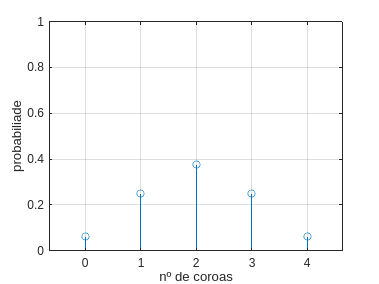

numExp = 1e4;
nLanc = 4;
% num de coroas pode ser de 0 a 4;
x = 0:1:4;
vetorNumCoroas = zeros(1,nLanc + 1);

for i = 1:numExp
    matrizLanc = rand(1,4) < 0.5;
    numCoroas = sum(matrizLanc);
    vetorNumCoroas(numCoroas + 1) = vetorNumCoroas(numCoroas + 1) + 1;
end

vetorMassaProb_x = vetorNumCoroas/numExp;

stem(x,vetorMassaProb_x);
ylim([0 1]);
xlabel('nº de coroas');
ylabel('probabiliade');
grid on;

b) Estimar o valor esperado, a variância e o desvio padrão de X com base em Px(x).

- O **valor esperado**, **E|X|**, de uma variável aleatória X é dado por:

**E[X]= (n) i=0 ∑ xi⋅p_x(xi)**, onde     

                                                                - xi são os valores possíveis da variável aleatória X

                                                                - p(xi) são as probabilidades associadas a cada valor xi

- A **variância**, **Var(X)**, de uma variável aleatória X é dada por:

**Var(X) = E[X²] - (E[X])²**

- O **desvio** **padrão**, σ(X), é dada por:

**sqrt(Var(X))**

% valor esperado:
x = 0:1:4;
numLanc = 4;
% do exercicio anterior, um dos resultados do vetor de probabilidades deu:
prob_a = [0.0642 0.2494 0.3743 0.2513 0.0608];
valorEsperado = 0;
valorEsperado_x2 = 0;

% valor esperado
for i = 1:length(x)
    valorEsperado = valorEsperado + x(i) * prob_a(i);
end

% variância
for i = 1:length(x)
    valorEsperado_x2 = valorEsperado_x2 + x(i)^2 * prob_a(i);
end
variancia = valorEsperado_x2 - valorEsperado^2;

% desvio padrão
desvioPadrao = sqrt(variancia);

disp(['valor esperado: ', num2str(valorEsperado)]);

valor esperado: 1.9951


disp(['variância: ', num2str(variancia)]);

variância: 1.0007


disp(['desvio padrão: ', num2str(desvioPadrao)]);

desvio padrão: 1.0003


c) Tipo da distribuição da variável aleatória X e qual a expressão teórica da sua função de probabilidade

**R:** Distribuição discreta (fruto de contagem). Mais especificamente, binomial.

Expressão:    P(X = k) = C(n,k) * p^k * (1-p)^(n-k)

d) Calcular os valores teóricos de a) e comparar com o obtido na simulação

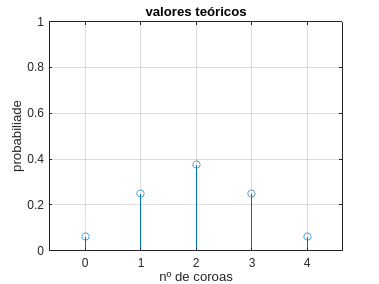

x = 0:1:4;
vetorProbT = zeros(1,5);
n = 4;
prob = 0.5;

function y = coefBinomial(n,k)
    y = factorial(n)/(factorial(k)*(factorial(n - k)));
end
% prob = prob de coroa (0.5)
% k = numero de coroas (está no X para cada situaçao)
% n = numero de lançamentos
% prob(xi) = factorial(n)/(factorial(k)*(factorial(n - k))) *
%            prob^k  * (1 - prob)^(n-k)
for i = 1:length(vetorProbT)
    vetorProbT(i) = coefBinomial(n,x(i)) * prob^x(i) * (1 - prob)^(n - x(i));
end

stem(x,vetorProbT);
ylim([0 1]);
title('valores teóricos');
xlabel('nº de coroas');
ylabel('probabiliade');
grid on;

**R: **Na alínea a) ---- um dos resultados: [0.0642 0.2494 0.3743 0.2513 0.0608] ---- os resultados rondam os valores teóricos, mas obviamente há sempre alguma diferença no que é obtido. No caso dos valores teóricos, a chance de zero e quatro coroas é igual, bem como a chance de 1 ou 3 coroas (visto que são casos complementares/opostos),

e)  Valores teóricos de E[X] e de Var(X) e comparar com a alínea b).

n = 4;      % num lançamentos
p = 0.5;
vetorCenarios = 0:1:4;
vetorProb = zeros(1,5);

for i = 1:length(vetorCenarios)
    k = vetorCenarios(i);
    vetorProb(i) = nchoosek(n,k)*(p^k)*(1-p)^(n-k); % prob de cada cenario
end

valorEsperado = 0;
for i = 1:length(vetorCenarios)
    valorEsperado = valorEsperado + vetorCenarios(i)*vetorProb(i);
end
valorEsperado

valorEsperado = 2


valorEsperado_x2 = 0;
for i = 1:length(vetorCenarios)
    valorEsperado_x2 = valorEsperado_x2 + vetorCenarios(i)^2*vetorProb(i);
end
variancia = valorEsperado_x2 - valorEsperado^2

variancia = 1

f)  Calcular com base nos valores teóricos

    i) Probabilidade de obter pelo menos de 2 coroas:

n = 4;      % num lançamentos
p = 0.5;
vetorCenarios = 0:1:4;
vetorProb = zeros(1,5);

for i = 1:length(vetorCenarios)
    k = vetorCenarios(i);
    vetorProb(i) = nchoosek(n,k)*(p^k)*(1-p)^(n-k); % prob de cada cenario
end
% [0 1 2 3 4]
prob_i = vetorProb(3) + vetorProb(4) + vetorProb(5)

prob_i = 0.6875

    ii) Probabilidade de obter até 1 coroa

prob_ii = 1 - prob_i

prob_ii = 0.3125

    iii) Probabilidade de obter entre 1 e 3 coroas

prob_iii = vetorProb(2) + vetorProb(3) + vetorProb(4)

prob_iii = 0.8750

#### **Ex4. Processo de fabrico produz ****30% de peças defeituosas****. Variável aleatória X - número de peças defeitusas numa ****amostra de 5 peças**** tomadas aleatóriamente.**

a) Por simulação

    i) Função massa de probabilidade de X:

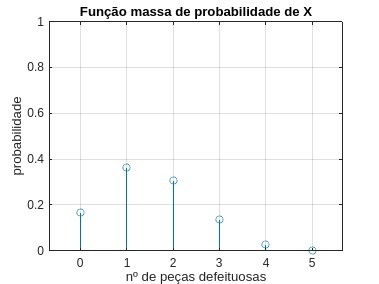

% %% teórico...
clear;
n = 5;      % amostras
p = 0.3;    % prob defeituosas
vetorCenarios = 0:1:5;
vetorProb = zeros(1,n+1);
% 
% for i = 1:length(vetorCenarios)
%     k = vetorCenarios(i);
%     vetorProb(i) = nchoosek(n,k)*(p^k)*(1-p)^(n-k); % prob de cada cenario
% end
% 
% stem(vetorCenarios,vetorProb);
% title('Função massa de probabilidade de X');
% xlabel('nº de peças defeituosas');
% ylabel('probabilidade')
% ylim([0 1]);
% grid on
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% por simulação (...)
numExp = 1e4;

for i = 1:numExp
    matrizPecas = rand(1,5) < p;
    numDef = sum(matrizPecas);      %% num peças defeituosas
    vetorProb(numDef+1) = vetorProb(numDef+1) + 1;
end

vetorMassaProb_x = vetorProb/numExp;
stem(vetorCenarios,vetorMassaProb_x);
title('Função massa de probabilidade de X');
xlabel('nº de peças defeituosas');
ylabel('probabilidade')
ylim([0 1]);
grid on

    ii) Gráfico de distribuição acumulada de probabilidades

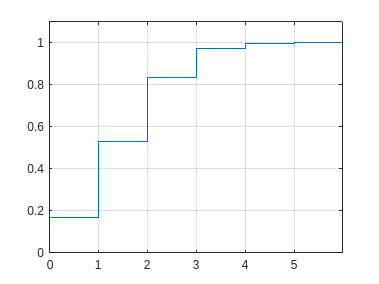

x = vetorCenarios;
prob_x = vetorMassaProb_x;
xx = [x 6];
prob_xx = [prob_x 0];

%% cumsum = cumulative sum
stairs(xx, cumsum(prob_xx))
ylim([0 1.1]);
xlim([0 6]);
xticks(x);
grid on;

    iii) Estimativa probabilidade de no máximo duas peças serem defeituosas

**R: **Por análise do gráfico probabilidade cumulativa: Prob('maximo de 2 peças defeituosas') = aprox 0.84

b) Analiticamente (teórico)

    i) Função de distribuição acumulada de X

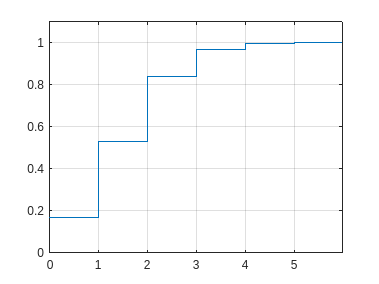

% função massa de prob de X teórica
clear;
n = 5;      % amostras
p = 0.3;    % prob defeituosas
vetorCenarios = 0:1:5;
vetorProb = zeros(1,n+1);

for i = 1:length(vetorCenarios)
    k = vetorCenarios(i);
    vetorProb(i) = nchoosek(n,k)*(p^k)*(1-p)^(n-k); % prob de cada cenario
end

% função de distribuição acumulada de X teórica
x = vetorCenarios;
prob_x = vetorProb;
xx = [x 6];
prob_xx = [prob_x 0];

%% cumsum = cumulative sum
stairs(xx, cumsum(prob_xx))
ylim([0 1.1]);
xlim([0 6]);
xticks(x);
grid on;

    ii) Probabilidade de, no máximo, duas peças serem defeitusas.

**R: **Por análise do gráfico probabilidade cumulativa: Prob('maximo de 2 peças defeituosas') =  0.83692

#### **Ex5. Motores de avião podem falhar com ****probabilidade p**** e as falhas são ****independentes entre motores****. O avião ****despenha-se caso mais de metade dos motores falhem****. **

#### **É preferível voar num avião com 2 ou 4 motores?**

Sugestão..

(1) obter expressões para a probabilidade de cada tipo de avião se despenhar em função de p e usar o quociente entre ambas para responder.

(2) efetuar os cálculos para um conjunto de valores concretos de p (ex.: p = logspace(-3,log10(1/2),100) e usar um gráfico mostrando simultaneamente as probabilidades de cada tipo de avião se despenhar

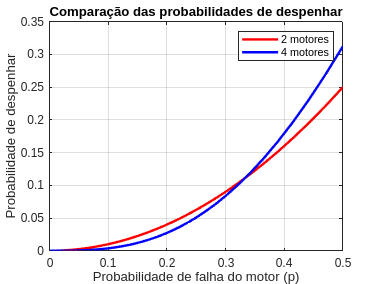

vetorProb = logspace(-3,log10(1/2),100);            % vetor 1x100
matrizProb = zeros(2,length(vetorProb));            % matriz 2x100  (1a linha - 2 motores)
%                                                           (2a linha - 4 motores)

n = 2;      % 2 motores
k = 2;      % despenha-se apenas se 2 motores falharem
for i = 1:length(vetorProb)
    p = vetorProb(i);
    matrizProb(1,i) = nchoosek(n,k)*(p^k)*(1-p)^(n-k);  % prob de despenhar para 
                                                        % cada valor de p
end

n = 4;      % 2 motores
k1 = 3;
k2 = 4;     % despenha-se caso 3 ou 4 motores falhem (> do que metade)
for i = 1:length(vetorProb)
    p = vetorProb(i);
    prob_3 = nchoosek(n,k1)*(p^k1)*(1-p)^(n-k1);           % prob de falharem 3 motores para cada valor de p
    prob_4 = nchoosek(n,k2)*(p^k2)*(1-p)^(n-k2);           % prob de falharem 4 motores para cada valor de p
    matrizProb(2,i) = prob_3 + prob_4;                  % prob de despenhar para cada valor de p 3 motores
end

figure;
plot(vetorProb, matrizProb(1, :), 'r', 'LineWidth', 2);  % 2 motores
hold on;
plot(vetorProb, matrizProb(2, :), 'b', 'LineWidth', 2);  % 4 motores
xlabel('Probabilidade de falha do motor (p)');
ylabel('Probabilidade de despenhar');
legend('2 motores', '4 motores');
grid on;
title('Comparação das probabilidades de despenhar');


% codigo do boia, menor e melhor lmao
vetorProb = logspace(-3,log10(1/2),100);
y_1 = p.*p;
y_2 = p.^4;
% ele calculou o valor do nchoosek à mao, daí estar como 1 (omitido) no y_1
% e 2a parte do y_2 e estar como 4 quando é nchoosek(4,3)
 
% y_2 = y_2 + 4.*(p.^3).*(1-.p):
% figure;
% hold on
% plot(p,y_1);
% plot(p,y_2);
% hold off;

#### **Ex6. Distribuição de Poisson - forma limite da distribuição binomial (n -> **∞, p -> 0, np constante) - pode ser usada para simplificar cálculos quando aplicável. 

#### **Fabrico de chips. Em média, por cada 1000 chips, um é defeituoso.**

a) Usando a distribuição binomial, calcular a probabilidade de em 8000 chips aparecerem 7 defeituosos?

n = 8000;
k = 7;
p = 1/1000;

prob_a = nchoosek(n,k)*(p^k)*(1-p)^(n-k)

prob_a = 0.1396

b) Calcular o mesmo mas usando a aproximação de Poisson.

            Lei de Poisson:        p_k = λ^k / k! * ( e^(- λ) )

                    λ = n*p

lambda = n*p;
prob_b = (lambda^k)/factorial(k) * (exp(-lambda))

prob_b = 0.1396

#### **Ex7. Chegam a um servidor de email em média ****15 mensagens por segundo**** (segue a lei de Poisson). Calcular a probabilidade de, num ****intervalo de 4 segundos****..**

a) O servidor não receber nenhuma mensagem

lambda = 4*15;
k = 0;
prob_a = (lambda^k)/factorial(k) * (exp(-lambda))

prob_a = 8.7565e-27

b) O servidor receber mais de 40 mensagens

kfor = 40;
prob_b = 0;

for k = 0:kfor
    prob_b = prob_b + (lambda^k)/factorial(k) * (exp(-lambda));
end

prob_b = 1 - prob_b

prob_b = 0.9960


% alternativamente, existe uma função do matlab que faz isto, ficando:
% lambda = 60;
% k = 40;
% prob = 1 - poisscdf(k, lambda)

#### **Ex8. O número de erros tipográficos numa página de um livro tem uma distribuição de Poisson com **λ = 0.02. 

#### Calcular a probabilidade de existir no máximo 1 erro num livro com 100 páginas. O número de erros de uma página é independente do número de erros em outras páginas.

lambda = 100*0.02;  % possível porque os erros são independentes
k = 1;

prob = (lambda^k)/factorial(k) * (exp(-lambda))

prob = 0.2707

    **Ex9. Variável aleatória X - classificações dos alunos de um determinado curso, contínua (nºs reais) e c/ distribuição normal (randn do matlab) (média 14 e desvio padrão 2). Através de ****simulação**** obter..:**

valorEsperado = 14;
desvio = 2;
n = 1e4;

    a) Probabilidade de um aluno do curso ter nota entre 12 e 16.

vetorNotas = desvio.*randn(1,n) + valorEsperado;

casosFav = sum(vetorNotas >= 12 & vetorNotas <= 16);

prob_a = casosFav / n

prob_a = 0.6828

    b) Probabilidade de todos os alunos terem notas entre 10 e 18.

% de modo a calcular a probabilidade de TODOS os alunos num curso terem
% notas entre 10 e 18, defini que são cursos de 80 alunos por exemplo
nAlunos = 80;
casosFav = 0;

for i = 1:n
    vetorNotas = desvio.*randn(1,nAlunos) + valorEsperado;
    if all(vetorNotas >= 10 & vetorNotas <= 18)
        casosFav = casosFav + 1;
    end
end

prob_b = casosFav / n

prob_b = 0.0237

    c) Probabilidade de um aluno passar (acima ou igual a 10)

vetorNotas = desvio.*randn(1,n) + valorEsperado;

casosFav = sum(vetorNotas >= 10);

prob_c = casosFav / n

prob_c = 0.9767